Initial and fianl configuration are as follows:

q0_init = 45*pi/180;
q0_final = 0;
t_init = 0;
t_final = 1;
qdot0_init = 0.5;
qdot0_final = 0;
qddot0_init = 1;
qddot0_final = 0;

syms t a0 a1 a2 a3 a4 a5

eq1 = a0 + a1*t_init + a2*t_init^2 + a3*t_init^3 + a4*t_init^4 + a5*t_init^5 -q0_init == 0;
eq2 = a1 + 2*a2*t_init + 3*a3*t_init^2 + 4*a4*t_init^3 + 5*a5*t_init^4  -qdot0_init == 0;
eq3 = 2*a2 + 6*a3*t_init + 12*a4*t_init^2 + 20*a5*t_init^3  -qddot0_init == 0;
eq4 = a0 + a1*t_final + a2*t_final^2 + a3*t_final^3 + a4*t_final^4 + a5*t_final^5 -q0_final == 0;
eq5 = a1 + 2*a2*t_final + 3*a3*t_final^2 + 4*a4*t_final^3 + 5*a5*t_final^4  -qdot0_final == 0;
eq6 = 2*a2 + 6*a3*t_final + 12*a4*t_final^2 + 20*a5*t_final^3  -qddot0_final == 0;


eq = [eq1;eq2;eq3;eq4;eq5;eq6];
sol = solve(eq,[a0 a1 a2 a3 a4 a5]);

a0 = sol.a0

$$a0 = 0.7854$$

a1 = sol.a1

$$a1 = 0.5000$$

a2 = sol.a2

$$a2 = 0.5000$$

a3 = sol.a3

$$a3 = -12.3540$$

a4 = sol.a4

$$a4 = 17.2810$$

a5 = sol.a5

$$a5 = -6.7124$$

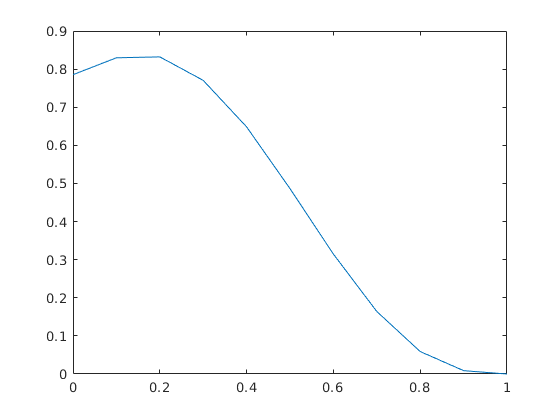


theta0 = [];
t = [];
thetadot0 =[];
thetaddot0 = [];
for i = t_init:0.1:t_final
    theta0 = [theta0; a0 + a1*i + a2*i^2 + a3*i^3 + a4*i^4 + a5*i^5];
    thetadot0 = [thetadot0; a1 + 2*a2*i + 3*a3*i^2 + 4*a4*i^3 + 5*a5*i^4];
    thetaddot0 = [thetaddot0; 2*a2 + 6*a3*i + 12*a4*i^2 + 20*a5*i^3];
    t = [t;i];
    
end
figure
plot(t,theta0)

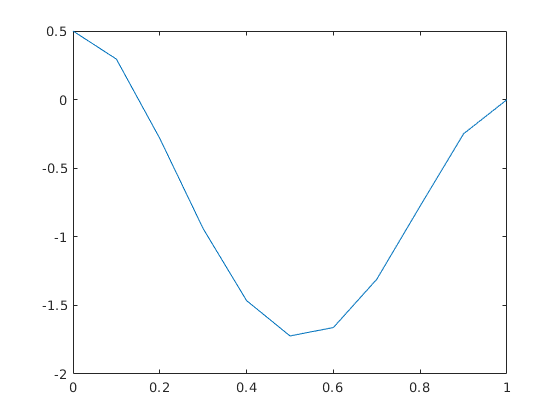

figure
plot(t,thetadot0)

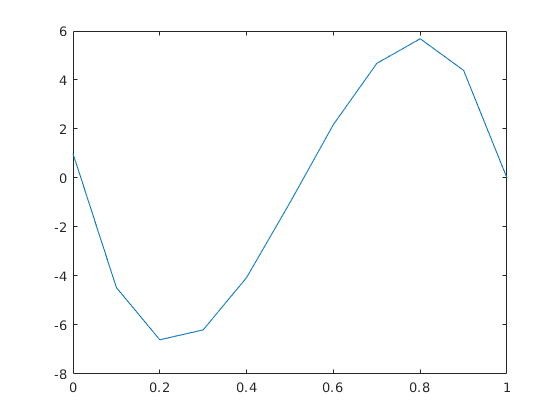

figure
plot(t,thetaddot0)